clear;clc;

load fisheriris;

## Data Processing

% Shuffle the dataset and pick 'split' number of samples for training
idx = randperm(size(meas,1));
X = meas(idx,:);
Y = zeros(size(species,1),1);
unq = unique(species);
for i = 1:size(unq,1)
    Y = Y + strcmp(unq{i}, species)*i;
end
Y = Y(idx,:);

split = 100;
X_train = X(1:split,:);
X_test = X(split+1:end,:);
Y_train = Y(1:split,:);
Y_test = Y(split+1:end,:);

D = size(X,2); K = size(unq,1);
Y_train_aug = zeros(size(X_train,1),K);
for k = 1:K
    Y_train_aug(:,k) = Y_train==k;
end

## Formulation

lr = 0.1;
epochs = 50;

% NN with 1 hidden layer
I = D; H1 =  5; O =  K;
w{1,1} = randn(I,H1); w{2,1} = randn(H1,O);

% NN with 2 hidden layers
% I = D; H1 =  5; H2 =  5; O =  K;
% w{1,1} = randn(I,H1); w{2,1} = randn(H1,H2); w{3,1} = randn(H2,O);

tic;
for t = 1:epochs
    for k = 1:length(X_train)
            % Random indices avoids local minima
            r = round(length(X_train).*rand(1,1));
            if r == 0
                r = r+1;
            end

            % r=k;
            
            L = size(w,1);
            % FORWARD PASS
            z{1,1} = X_train(r,:)*w{1,1};
            a{1,1} = logsig(z{1,1});
            for l=2:L
                z{l,1} = a{l-1,1}*w{l,1};
                a{l,1} = logsig(z{l,1});
            end
            
            % ERROR CALCULATION
            e = Y_train_aug(r,:)-a{end,1};
            
            % BACKWARD PASS
            d{L,1} = dlogsig(z{end,1},a{end,1}).*(e);
            for l=L-1:-1:1
                d{l,1} = dlogsig(z{l,1},a{l,1}).*(d{l+1,1}*w{l+1,1}');
            end            
            
            for l=L:-1:2
                w{l,1} = w{l,1} + lr.*a{l-1,1}'*d{l,1};
            end
            w{1,1} = w{1,1} + lr.*X_train(r,:)'*d{1,1};
    end
    
    % Error after each epoch
    err(t) = sum(e.^2);

    % Testing the X_test using the updated weight matrices
    z{1,1} = X_test*w{1,1};
    a{1,1} = logsig(z{1,1});
    for l=2:L
        z{l,1} = a{l-1,1}*w{l,1};
        a{l,1} = logsig(z{l,1});
    end
    res = a{end,1};

    % Predicting the values for X_test
    predict = zeros(size(Y_test));
    for k = 1:length(X_test)
        [val, col] = max(res(k,:));
        predict(k,:) = col;
    end

    % Classification Rate
    acc(t) = (sum(predict==Y_test)/length(X_test))*100;
end
toc;

Elapsed time is 0.137835 seconds.


## Classification

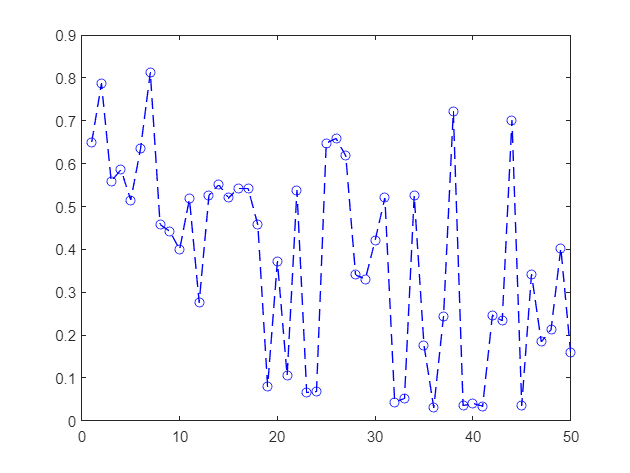

figure;
plot(1:epochs, err, 'b--o');

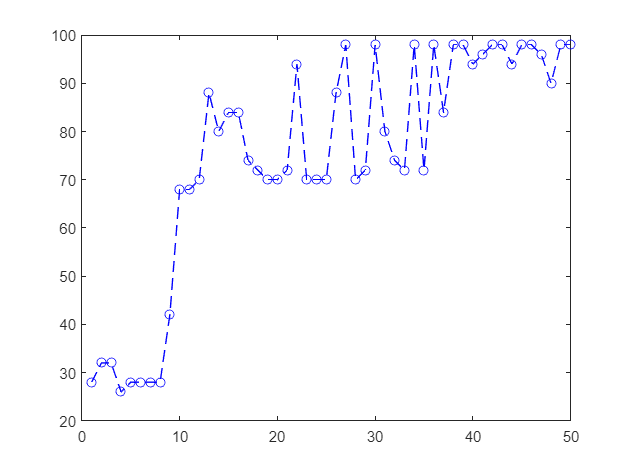

figure;
plot(1:epochs, acc, 'b--o');